## Questions from the paper.

(a). 

(b). 

## KaiC Model

Autophosphorylation model:


$${\frac{dK_p}{dt}} = \left({b \frac{K_P^n}{K_M^n+K_P^n}} + 0.1\right)\left(K_{tot}-K_P\right) - P_P.K_P$$


Dephosphorylation model:


$${\frac{dP_p}{dt}} = k\left({ a\frac{K_P^6}{K_M^6+K_P^6}} - P_P\right)$$


#### Parameters

% For autophosphorylation.
Ktot = 3;                   %Total kinase (phosph. and unphosph.)
K_P = [0:Ktot/100:Ktot];    %Phosphorylated (active) kinase
K_M = 1;                    %K_M for activating of the kinase & phosphatase
b = 0.8;                    %scaling in dK_P/dt
n = 6;                      %cooperativity

% For dephosphorylation.
a = 2;                      %scaling in dP_P/dt

#### Nullclines

Parts (c) and (d).

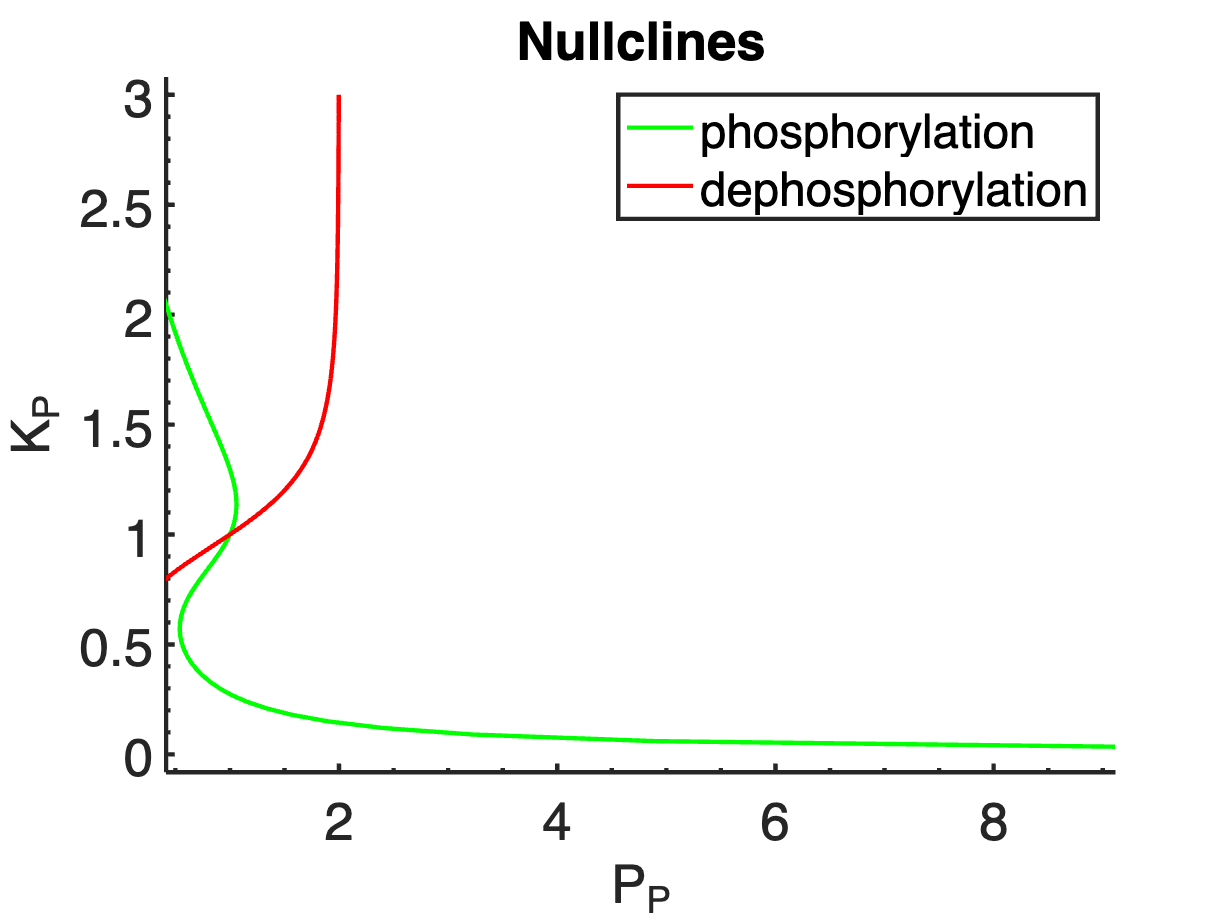

% the dKP nullcline (Psolve):
Psolve_phospho = (b.*K_P.^n./(K_M^n + K_P.^n)+0.1).*(Ktot -K_P)./K_P;

% the dKP nullcline (Psolve):
Psolve_dephospho = a.*K_P.^n./(K_M^n + K_P.^n);

figure; hold on; zoom on;
% plot nullcline.
plot(Psolve_phospho, K_P, 'g-');
plot(Psolve_dephospho, K_P, 'r-');
% set plot parameters.
title('Nullclines');
xlabel('P_P');
ylabel('K_P');
legend('phosphorylation', 'dephosphorylation');
PrettyFig;

(e) The fixed point occurs at the intersection of the nullclines, at $(P_P = 1, K_P = 1)$.

(f) The fixed point is .

(g)

#### Verifying that the equations oscillate

Part (h).

The oscillations are plotted for **k = 0.0009**. At this value, the period of the oscillation is **T = ~1440** (see first complete red curve from T = *~1250 to ~2690*, for instance).

Further, the plots verify that equations (1) and (2) do in fact oscillate.

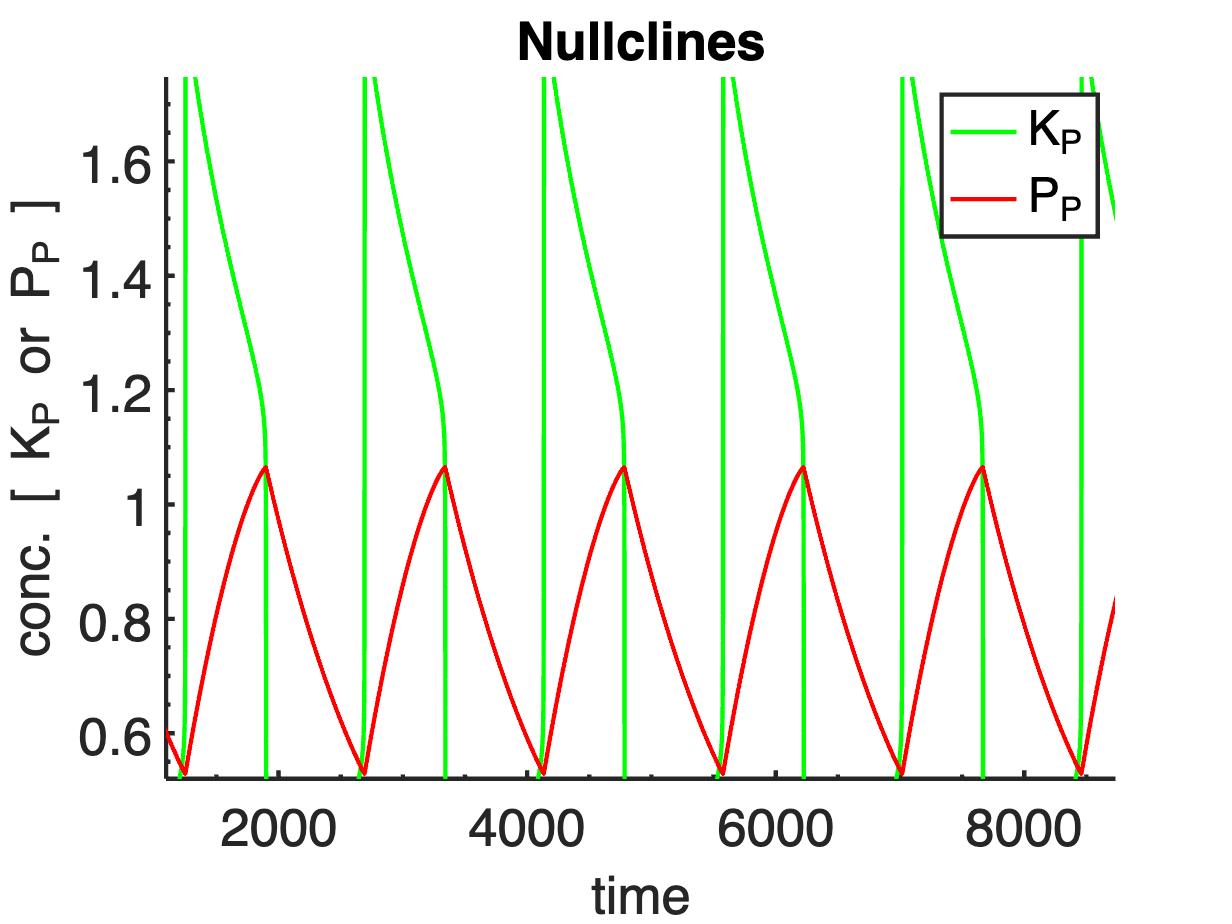

k = 0.0009;
% plot for k = 0.001;
dydt = @(t,y)[
    (Ktot-y(1)).*(b.*y(1).^n./(K_M^n + y(1).^n)+0.1)-y(2).*y(1); ...
    k*(a.*y(1).^n./(K_M^n + y(1).^n)-y(2))
];
% numerical integration.
[T,Y] = ode45(dydt,[0,10000],[1.25 0.75]);

figure; hold on; zoom on;
plot(T, Y(:, 1), 'g-');
plot(T, Y(:, 2), 'r-');
% set plot parameters.
title('Nullclines');
xlabel('time');
ylabel('conc. [ K_P or P_P ]');
legend('K_P', 'P_P');
PrettyFig;

#### Phase-plane plot

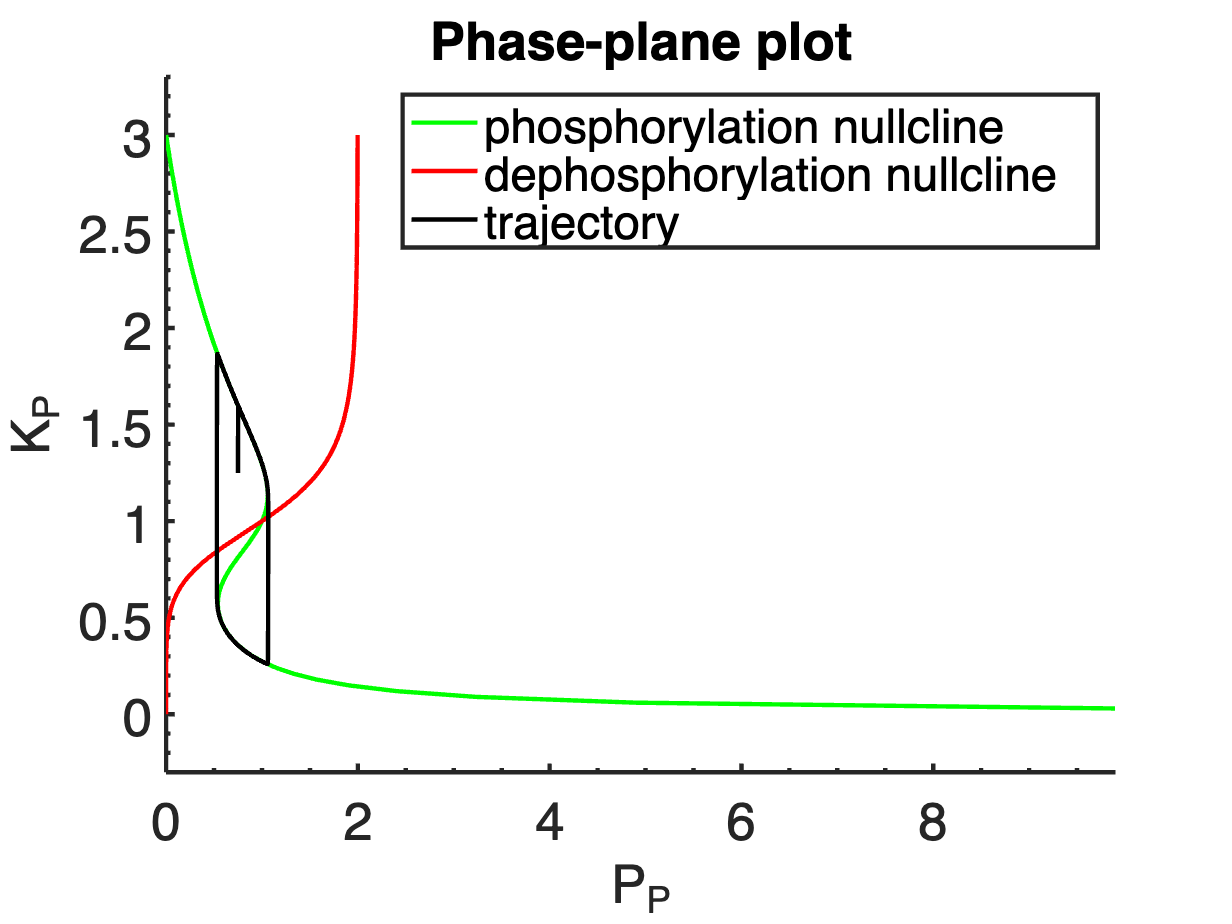

figure; hold on; zoom on;
% plot nullcline.
plot(Psolve_phospho, K_P, 'g-');
plot(Psolve_dephospho, K_P, 'r-');
plot(Y(:, 2), Y(:, 1), 'k-');
% set plot parameters.
title('Phase-plane plot');
xlabel('P_P');
ylabel('K_P');
legend('phosphorylation nullcline', 'dephosphorylation nullcline', 'trajectory');
PrettyFig;

#### Oscillation trajectory over time -- GIF image.